**5 Comparison Bode Plots of Derived DC-DC Buck Converter with Derived Type III Compensator Controller**

clc; 
clear all; 
close all;

%Identify Transfer Function Variable
s = tf('s');

% Buck Converter Values
R = 10;         % Load resistance (Ohm)
L = 350e-6;     % Inductor value (H)
C = 100e-6;     % Capacitor value (F)
RL = 0.050;     % Inductor resistance (Ohm)
RC = 0.025;     % Capacitor resistance (Ohm)
Vin = 12;       % Input Voltage value (V)

% Transfer Function for Real Buck Converter
REALBUCKTOP = 1+(C*RC)*s;
REALBUCKBOTTOM = 1+(RL/R)+(L/R+RC*C+RL*C+(RL*RC*C)/R)*s+((R+RC)/R)*L*C*(s^2);
REALBUCKTF = Vin*(REALBUCKTOP/REALBUCKBOTTOM)

% Type III Compensator Controller Values
R1 = 20e3;      % Resistor R1 value (Ohm)
R2 = 12.4e3;    % Resistor R2 value (Ohm)
R3 = 568;       % Resistor R3 value (Ohm)
C1 = 200e-12;   % Capacitor C1 value (F)
C2 = 10.2e-9;   % Capacitor C2 value (F)
C3 = 3.7e-9;    % Capacitor C3 value (F) (Control this to make phase shift up and down) (Ex:30.4e-9)

% Table of Type III Compensator Controller Values Displayed
compValues = [R1, R2, R3, C1, C2, C3];
disp(table(R1, R2, R3, C1, C2, C3))

     R1       R2      R3      C1         C2         C3   
    _____    _____    ___    _____    ________    _______

    20000    12400    568    2e-10    1.02e-08    3.7e-09




% Derived Transfer Function for Type III Compensator Controller
COMPTOP =(s*C3*(R1+R3)+1) * (s*C2*R2+1);
COMPBOTTOM =(s*R1*(C1+C2)) * (s*C3*R3+1) * (s*((C1*C2)/(C1+C2))*R2+1);
COMPLETECOMP = (-1)*COMPTOP/COMPBOTTOM

COMPLETECOMP =
 
       -9.625e-09 s^2 - 0.0002026 s - 1
  ------------------------------------------
  1.063e-15 s^3 + 9.431e-10 s^2 + 0.000208 s
 
Continuous-time transfer function.
Model Properties



% Comparison Bode Plot Displayed
figure()
options = bodeoptions;
options.FreqUnits = 'rad/s';
bode(COMPLETECOMP, options); hold on;
bode(REALBUCKTF,options); hold on;
bode(REALBUCKTF*COMPLETECOMP,options);
grid on
legend('Controller', 'Buck', 'Complete Loop')

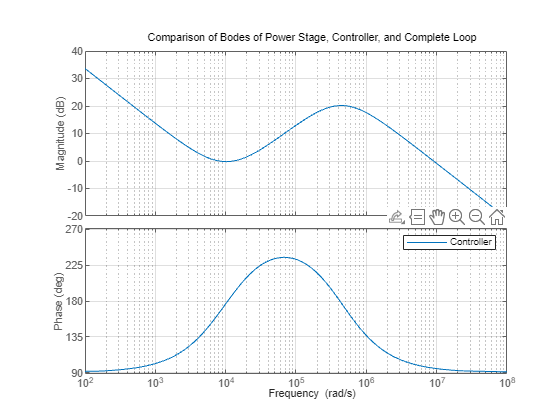

title('Comparison of Bodes of Power Stage, Controller, and Complete Loop')


% Margin Bode Plot Displayed
figure()
margin(COMPLETECOMP*REALBUCKTF, options)

Unrecognized function or variable 'REALBUCKTF'.

grid on